# Motor Sequence Learning (MSL) - TMR Experiment

Analysis of the behavioral data

% Ella Gabitov (gabitovella@gmail.com), 15 December 2022

## Init

% Regular text interpreter
set(0,'DefaultTextInterpreter','none')

### Data Info

[actfile_dpath, ~, ~] = fileparts(matlab.desktop.editor.getActiveFilename);
[main_dpath, ~, ~] = fileparts(actfile_dpath);

add2path = {...
    fullfile(main_dpath, 'analysis');
    };
for i = 1 : length(add2path)
    addpath(add2path{i});
end

% Path to the directory with data for analysis
data_dpath = fullfile(main_dpath, 'results');


### Subjects for Analysis

% A list of subjects
% The data of each subject is stored in the directory with the same name as the subject identifier

% Get all subjects from the src directory
list_dir = dir(data_dpath);
subjects = {list_dir([list_dir(:).isdir]).name};
subjects(contains(subjects, '.')) = []; % Should not contain dots

% Specify subjects explicitly
% subjects = {...
%     'Subject1'...
%     'Subject2'...
%     'Subject3'...
%     };


## Performance Duration

sess_lbl = 'pre-sleep test'

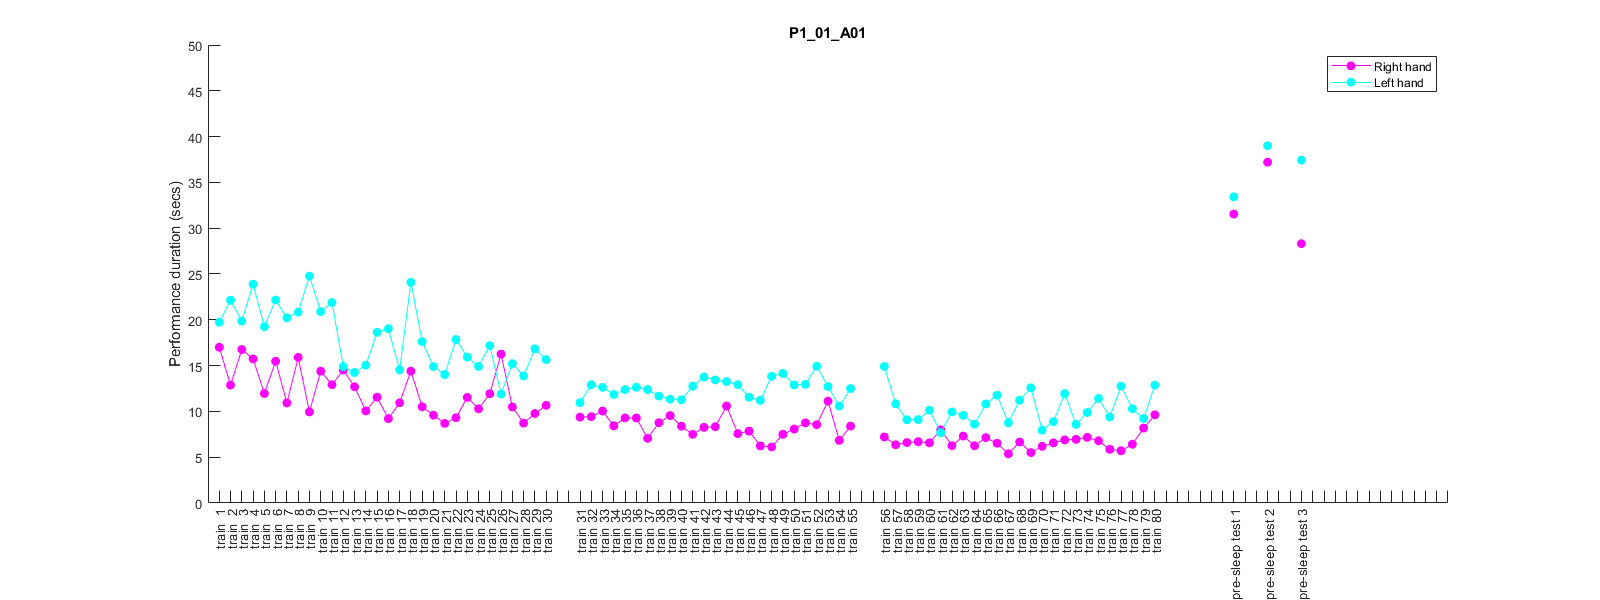

% Plot properties
y_label = 'Performance duration (secs)';
x_lim = [0 110];
y_lim = [0 50];
x_ticks = 1:110;
x_tick_labels{1, length(x_lim)} = {''};

% Sessions for analysis
sessions = {'PreSleep_training', 'PreSleep_test', 'PostSleep_test'};

for i_subj = 1 : length(subjects)
    subj = subjects{i_subj};
    data_subj_dpath = fullfile(data_dpath, subj);

    % Create a new figure
    f = figure();
    x0 = 10; y0 = 10; width = 1600; hight = 600;
    f.Position = [x0, y0, width, hight];

    % Is used to calculate the next value along the x axis
    x_end = 0;

    right_is_labeled = 0;
    left_is_labeled = 0;

    for i_sess = 1 : length(sessions)
        list_dir = dir(fullfile(data_subj_dpath, [subj, '_', sessions{i_sess}, '*.mat']));
        fnames = {list_dir.name};

        if isempty(fnames)
            continue;
        end

        switch sessions{i_sess}
            case 'PreSleep_training'
                sess_lbl = 'train';
            case 'PreSleep_test'
                sess_lbl = 'pre-sleep test'
            case 'PostSleep_test'
                sess_lbl = 'post-sleep test'
        end

        % Count blocks to plot
        count_blocks = 0;
        for i_fname = 1 : length(fnames)
            src_fpath = fullfile(data_subj_dpath, fnames{i_fname});
            
            % Load the data
            data_loaded = load(src_fpath);
            blocks_info = data_loaded.blocks.info;
            input_onsets = data_loaded.blocks.input_onsets;

            durations = input_onsets(:, end) - input_onsets(:, 1);

            is_right = strcmp(blocks_info.hand, 'right');
            is_left = strcmp(blocks_info.hand, 'left');

            x = x_end+1 : x_end+length(durations)/2;
            labels = cellstr(strcat(sess_lbl, {' '}, num2str([count_blocks+1 : count_blocks+length(x)]')));
            count_blocks = count_blocks+length(x);
            x_tick_labels(x) = labels;

            % --- RIGHT HAND

            % Magenta color - circle markers - dashed line
            plot_str = 'm o -';
            marker_face_color = 'm';
            
            % Add to plot and add the hand label if needed
            if right_is_labeled
                p = plot(x, durations(is_right), plot_str, 'HandleVisibility', 'off');
            else
                p = plot(x, durations(is_right), plot_str, 'DisplayName', 'Right hand');
                box off;
                title(subj);
                ylabel(y_label);
                xlim(x_lim);
                ylim(y_lim);
                legend('-DynamicLegend');
                legend('show');
                right_is_labeled = 1;
            end
            p.MarkerFaceColor = marker_face_color;
            xticks(x_ticks);
            xticklabels(x_tick_labels);
            drawnow;
            hold on;

            % --- LEFT HAND

            % Cyan color - circle markers - dashed line
            plot_str = 'c o -'; 
            marker_face_color = 'c';
            
            % Add to plot and add the hand label if needed
            if left_is_labeled
                p = plot(x, durations(is_left), plot_str, 'HandleVisibility', 'off');
            else
                p = plot(x, durations(is_left), plot_str, 'DisplayName', 'Left hand');
                box off;
                title(subj);
                ylabel(y_label);
                xlim(x_lim);
                ylim(y_lim);
                legend('-DynamicLegend');
                legend('show');
                left_is_labeled = 1;
            end
            p.MarkerFaceColor = marker_face_color;
            xticks(x_ticks);
            xticklabels(x_tick_labels);
            drawnow;
            hold on;

            % Add gap before plotting the data for the next phase of the current session
            x_end = x_end + length(x) + 2;

        end

        % Add gap before plotting the data for the next session
        x_end = x_end + 4;

    end

    hold off;

end

## Clear & Close

for i = 1 : length(add2path)
    rmpath(add2path{i});
end

clearvars;
